# Example 5.1: Estimation with Correct Postulated Model

Note: this script reproduces Example 5.1 (Section 5.1.1) of **Statistics for Chemical Engineers**: least-squares estimation of theta in Y = theta*X + noise, with true theta = 2. Victor Z UW-Madison, 2020 illustrate scalar linear estimation

clc; clear all; close all hidden;

## Data

generate data for input

rng(0)
S=100;
xobs=rand(S,1);

% generate true output
theta=2;
y=theta*xobs;

% add noise
sigma=0.25;
eps=normrnd(0,sigma,S,1);
yobs=y+eps;

## Estimate, fit, and residuals

now get estimate theta that extracts max knowledge from data

htheta=(xobs'*yobs)/(xobs'*xobs)

htheta =           1.96

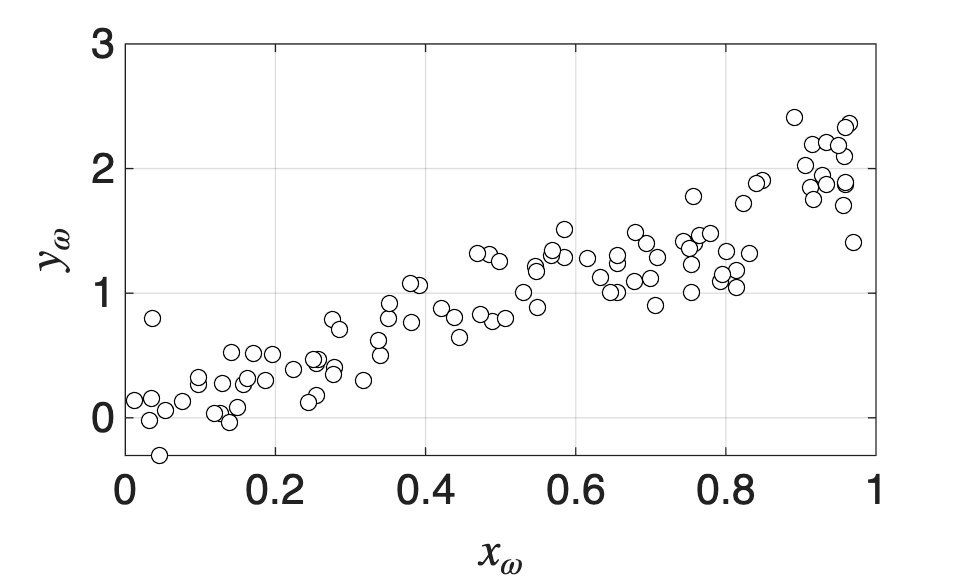


% plot model prediction
ypred=htheta*xobs;

figure(3)
plot(xobs,yobs,'blacko','MarkerFaceColor','w')
hold on
grid on
xlabel('$x_\omega$','Interpreter','latex','FontSize',16)
ylabel('$y_\omega$','Interpreter','latex','FontSize',16)
set(gca,'FontSize',16)
print -depsc ch5_lin_est.eps


figure(1)
subplot(2,2,1)
plot(xobs,ypred,'black-','LineWidth',1.5)
hold on
plot(xobs,yobs,'blacko','MarkerFaceColor','w')
hold on
grid on
legend('Model','Data','location','southeast')
xlabel('$x_\omega$','Interpreter','latex','FontSize',14)
ylabel('$y_\omega$','Interpreter','latex','FontSize',14)

% parity plot
subplot(2,2,2)
yy=linspace(min(yobs),max(yobs))

yy =          -0.30         -0.27         -0.25         -0.22         -0.19         -0.16         -0.14         -0.11         -0.08         -0.06         -0.03         -0.00          0.03          0.05          0.08          0.11          0.14          0.16          0.19          0.22          0.25          0.27          0.30          0.33          0.36          0.38          0.41          0.44          0.47          0.49          0.52          0.55          0.58          0.60          0.63          0.66          0.69          0.71          0.74          0.77          0.80          0.82          0.85          0.88          0.90          0.93          0.96          0.99          1.01          1.04


plot(yy,yy,'black-','LineWidth',1.5)
hold on
plot(yobs,ypred,'blacko','MarkerFaceColor','w')
axis([min(yobs) max(yobs) min(yobs) max(yobs)])
grid on
hold on
xlabel('$y_\omega$','Interpreter','latex','FontSize',14)
ylabel('$\hat{y}_\omega$','Interpreter','latex','FontSize',14)

% plot residuals
epsm=yobs-ypred

epsm =          -0.42
          0.24
         -0.22
          0.06
         -0.11
          0.08
         -0.14
          0.14
          0.22
          0.46
         -0.04
         -0.50
         -0.17
          0.36
         -0.24


xx=linspace(0,S)

xx =              0          1.01          2.02          3.03          4.04          5.05          6.06          7.07          8.08          9.09         10.10         11.11         12.12         13.13         14.14         15.15         16.16         17.17         18.18         19.19         20.20         21.21         22.22         23.23         24.24         25.25         26.26         27.27         28.28         29.29         30.30         31.31         32.32         33.33         34.34         35.35         36.36         37.37         38.38         39.39         40.40         41.41         42.42         43.43         44.44         45.45         46.46         47.47         48.48         49.49


yy=linspace(0,0)

yy =              0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0


subplot(2,2,3)
plot(xx,yy,'black-','LineWidth',1.5)
hold on
plot(epsm,'blacko','MarkerFaceColor','w')
axis([0,S,-3*sigma,+3*sigma])
hold on
grid on
xlabel('$\omega$','Interpreter','latex','FontSize',14)
ylabel('$\epsilon_\omega$','Interpreter','latex','FontSize',14)

pd = fitdist(epsm,'Normal')

pd =   NormalDistribution

  Normal distribution
       mu = -0.00477203   [-0.055254, 0.04571]
    sigma =    0.254418   [0.223381, 0.295551]



subplot(2,2,4)
histogram(epsm,'BinWidth',0.1,'Normalization','pdf','EdgeColor','black','FaceColor','none','LineWidth',1)
hold on
xx=linspace(-0.75,0.75)

xx =          -0.75         -0.73         -0.72         -0.70         -0.69         -0.67         -0.66         -0.64         -0.63         -0.61         -0.60         -0.58         -0.57         -0.55         -0.54         -0.52         -0.51         -0.49         -0.48         -0.46         -0.45         -0.43         -0.42         -0.40         -0.39         -0.37         -0.36         -0.34         -0.33         -0.31         -0.30         -0.28         -0.27         -0.25         -0.23         -0.22         -0.20         -0.19         -0.17         -0.16         -0.14         -0.13         -0.11         -0.10         -0.08         -0.07         -0.05         -0.04         -0.02         -0.01


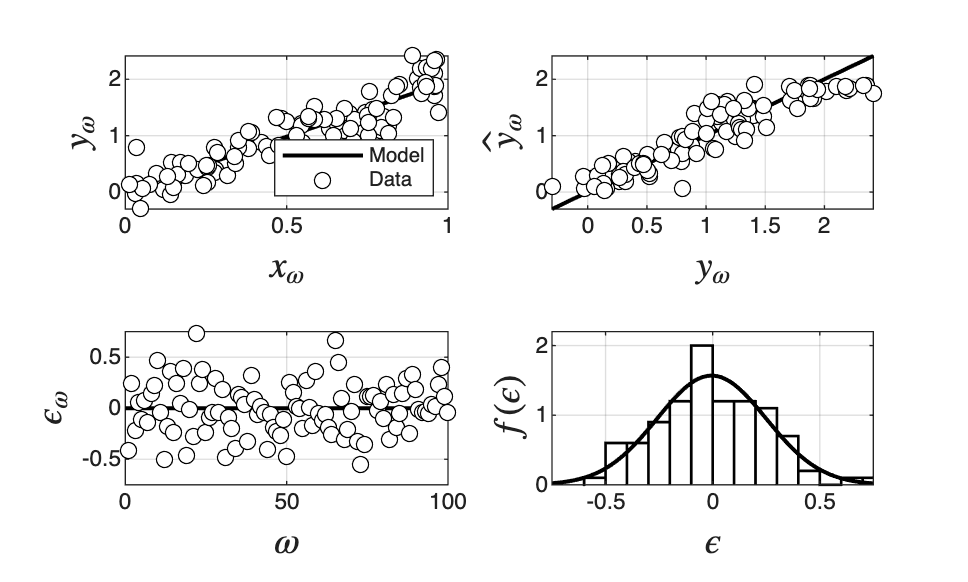

plot(xx,normpdf(xx,pd.mu,pd.sigma),'black-','LineWidth',1.5)
axis([-0.75 0.75 0 2.2])
grid on
xlabel('$\epsilon$','Interpreter','latex','FontSize',14)
ylabel('$f(\epsilon)$','Interpreter','latex','FontSize',14)
print -depsc ch5_results_lin_est.eps

## SSE(theta) with more data

now lets evaluate how SSE(theta) varies with amount of data available generate data for input

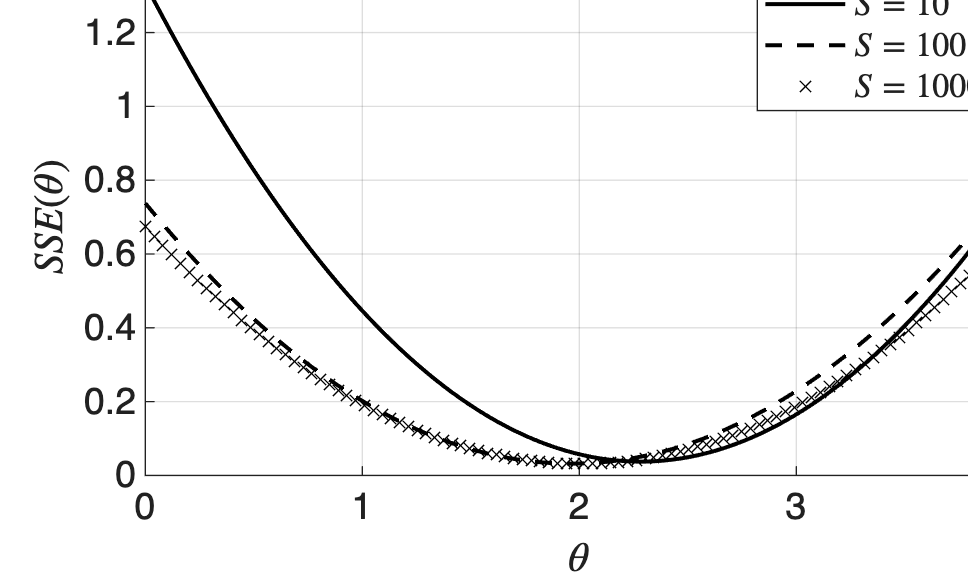

rng(0)
S=10;
xobs=rand(S,1);

% generate true output
theta=2;
y=theta*xobs;

% add noise
eps=normrnd(0,sigma,S,1);
yobs=y+eps;

% span theta
thetav=linspace(0,4);

for k=1:length(thetav)
    ym=thetav(k)*xobs;
    Sf(k)=0.5*(ym-yobs)'*(ym-yobs);
end

figure(2)
plot(thetav,(1/S)*Sf,'black-','LineWidth',1.5)
hold on

% generate data for input
rng(0)
S=100;
xobs=rand(S,1);

% generate true output
theta=2;
y=theta*xobs;

% add noise
eps=normrnd(0,sigma,S,1);
yobs=y+eps;

% span theta
thetav=linspace(0,4);

for k=1:length(thetav)
    ym=thetav(k)*xobs;
    Sf(k)=0.5*(ym-yobs)'*(ym-yobs);
end

figure(2)
plot(thetav,(1/S)*Sf,'black--','LineWidth',1.5)


% generate data for input
rng(0)
S=1000;
xobs=rand(S,1);

% generate true output
theta=2;
y=theta*xobs;

% add noise
eps=normrnd(0,sigma,S,1);
yobs=y+eps;

% span theta
thetav=linspace(0,4);

for k=1:length(thetav)
    ym=thetav(k)*xobs;
    Sf(k)=0.5*(ym-yobs)'*(ym-yobs);
end

figure(2)
plot(thetav,(1/S)*Sf,'blackx')
hold on
grid on
xlabel('$\theta$','Interpreter','latex','FontSize',16)
ylabel('$SSE(\theta)$','Interpreter','latex','FontSize',16)
set(gca,'FontSize',14)
legend('$S=10$','$S=100$','$S=1000$','Interpreter','latex')
print -depsc ch5_sharpness_lin_est.eps

## Note

As in the book, with S = 10 the SSE is minimized at theta of about 2.2, and with S = 100 or 1000 close to 2: more data helps identify the true parameter.